# Process for computing the 'X-Factor' in the golf swing

This script uses MATLAB functions to read in raw data from the Golf Biodynamics system.

## Clear workspace and set up directories and files

For this code to run correctly, there must be a **data** folder within the current directory containing the data. This script must be in MATLAB's search path.

clearvars; close all

File name to read in

filename = fullfile('data','P1_C2_T1.txt');

Read in data

golfData = csvread(filename, 9, 0);

## Extract X-Factor data from raw data files

Calculate the X-Factor throughout the swing

xfVector = golfData(:,17) - golfData(:,14);

Determine the frame number of the start of the downswing and extract the X-Factor value.

[minVal,minIndex] = min(golfData(:,14));

xf = xfVector(minIndex);

Calculate the maximum X-Factor (actually minimum because angles are negative in the backswing).

[xfMin,xfMinInd] = min(xfVector);

Determine the number of frames between the start of the downswing and the maximum X-Factor.

framesToMin = xfMinInd - minIndex;

Convert from frames to seconds.

timeToMin = framesToMin / 250;

X-Factor Stretch

stretch = xf - xfMin

stretch = 8.0660

## Plot X-Factor data

This plot shows the pelvis and thorax axial rotation angles. An angle of 0 degrees indicates the segments are aligned with the target line. Circles highlight the start of the downswing event and maximum X-Factor. The difference between X-Factor at the start of the downswing and maximum X-Factor is known as 'X-Factor Stretch' (see *stretch* in previous section).

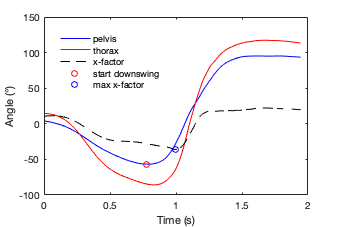

figure('Units', 'centimeters',...
    'Position', [5 5 12 8])

frames = 1 : length(golfData);

time = frames / 250;

plot(time, golfData(:,14), 'b-')

hold on

plot(time, golfData(:,17), 'r-')

plot(time, xfVector, 'k--')

plot(time(minIndex), minVal, 'ro')

plot(time(xfMinInd), xfMin, 'bo')

xlabel('Time (s)'); ylabel('Angle (°)')

legend({'pelvis','thorax','x-factor',...
    'start downswing','max x-factor'}, ...
    'Location', 'best',...
    'Box', 'off')

set(gcf,'Color','w')